inputVoltage = 6;                                                                                                                                                                                                                                                                                                                                                        inputVoltage = 6;
outputVoltage = 12;
dutyCycle = 1-inputVoltage/outputVoltage;
inductor = 833e-6;
capacitor = 470e-6;
resistor = 47;
inductorCurrent = outputVoltage/resistor/(1-dutyCycle);
openLoopGain = inputVoltage/inductor/capacitor;
openLoopZero = -inductorCurrent*inductor/inputVoltage;
SwitchingFreq = 1e5;

undampedNaturalFreq = sqrt((1-dutyCycle)^2/inductor/capacitor);
%undamped natural frequency
dampingRatio = 1/resistor/capacitor/2/undampedNaturalFreq;
%damping ratio

G = tf([openLoopGain*openLoopZero openLoopGain],[1 1/resistor/capacitor 1/inductor/capacitor]);
Gminimal = tf([openLoopGain*-openLoopZero openLoopGain],[1 1/resistor/capacitor 1/inductor/capacitor]); 

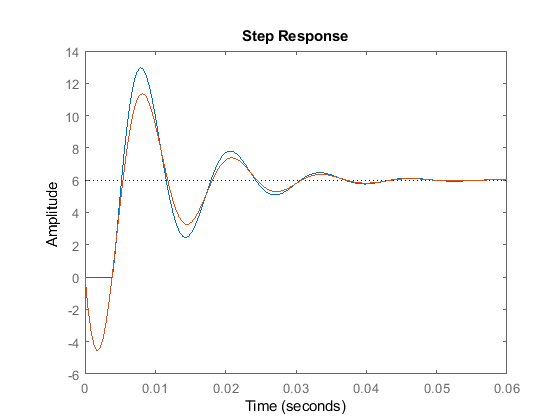

%use a first-order filter with a 20 second time constant to capture low-frequency disturbances.
s = tf('s');
% Process
%P = exp(2*openLoopZero*s) * Gminimal;%will be replaced by boost model in the future.
P = exp(-0.004*s) * Gminimal;
step(P);
hold on;
step(G);
hold off;

we use step response graph to show that our approximation is good. As is show in the graph on the right side, the two graphs the two graphs are apprimately the same expect for the first 0.001 second where the oringinal transfer function(TF for boost converter) experience an undershoot while the approxiamted transfer function(use delay to replace overshoot) remains zero.

G.InputName = 'u';
G.OutputName = 'y0';

% Prediction model
Gp = Gminimal;
Gp.InputName = 'u';
Gp.OutputName = 'yp';
%Gpd = c2d(Gp,SwitchingFreq);

%Dp = exp(2*openLoopZero*s);
Dp = exp(-0.004*s);
Dp.InputName = 'yp'; Dp.OutputName = 'y1';
%Dpd = c2d(Dp,SwitchingFreq)

% Overall plant
S1 = sumblk('ym = yp + dp');
S2 = sumblk('dp = y0 - y1');
Plant = connect(G,Gp,Dp,S1,S2,'u','ym');

Options = pidtuneOptions('PhaseMargin',60);
C = pidtune(Plant,pidstd(1,1,1),Options);
C.InputName = 'e';
C.OutputName = 'u';
C


C =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 0.0401, Ti = 0.00177, Td = 0.000442
 
Continuous-time PID controller in standard form




%Openloop_smith = connect(P,Gp,Dp,S1,S2,'u','ym');

This is the basic structure of simth predictor. The whole structure can be found in my onenote. Here We use Gp and Dp in series to represent our approximate model. And we also use c2d to calculate its discreate transfer function so as to implement it into our controller.

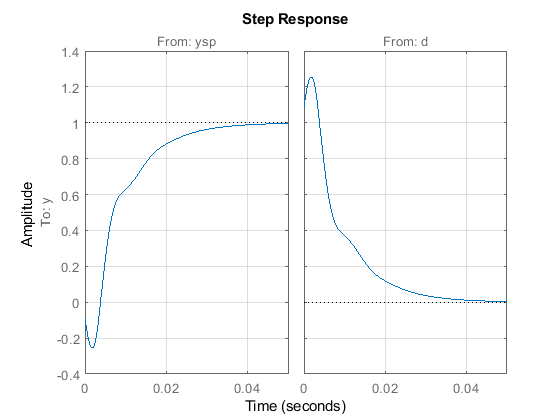

% Assemble closed-loop model from [y_sp,d] to y
Sum1 = sumblk('e = ysp - yp - dy');
Sum2 = sumblk('y = y0 + d');
Sum3 = sumblk('dy = y - y1');
T = connect(G,Gp,Dp,C,Sum1,Sum2,Sum3,{'ysp','d'},'y');
step(T),grid on
hold on

Cpi = pidtune(G,pidstd(1,1,1),Options);
Cpi


Cpi =
 
             1      1          
  Kp * (1 + ---- * --- + Td * s)
             Ti     s          

  with Kp = 3.27e-05, Ti = 4.45e-06, Td = 1.11e-06
 
Continuous-time PID controller in standard form



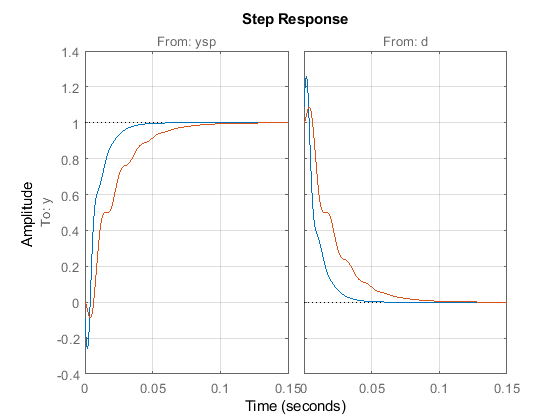

Tpi = feedback([G*Cpi,1],1,1,1);  % closed-loop model [ysp;d]->y
Tpi.InputName = {'ysp' 'd'};

step(Tpi)
hold off